mea_max = measure_white(ol,cs);

Unrecognized function or variable 'cs'.

mea_min = measure_black(ol,cs);

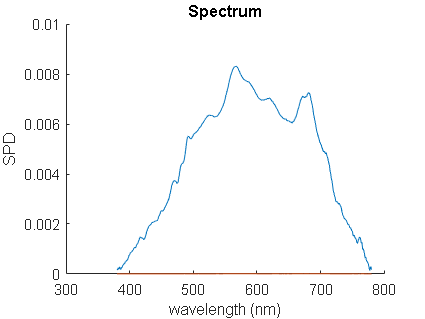

load('runme_data','M','B')

d65 = B;

spd_target_orig = d65;

clf
hold on
ols.speC_max.plot
ols.speC_min.plot

spd_max = ols.speC_max.amplitude;

sc = 1

sc = 1

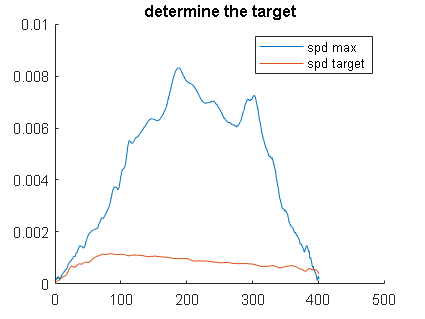

spd_target = spd_target_orig .* sc;
clf
hold on
plot(spd_max)
plot(spd_target)
legend('spd max','spd target')
title('determine the target')

ref_target_orig = (spd_target - spd_0) ./ (spd_max - spd_0);
ref_target = min(1,ref_target_orig);
ref_target()

clf
hold on
plot(ref_target_orig)
plot(ref_target)
title('the target reflectance')

ref_m = ls.col_spec';

vec_a_orig = R_callRsolver1024(ref_m,ref_target);

vec_a = vec_a_orig;
vec_a = min(1,vec_a);
vec_a = max(0,vec_a);

clf
hold on
plot(vec_a_orig)
plot(vec_a)
legend('original solution','trimmed solution')
title('the solution given by R')

clf
hold on
plot(ref_target)
ref = ref_m * vec_a;
plot(ref)
legend('target','calculated')
title('reflectance')

clf
hold on
plot(spd_target)
spd = spd_max .* ref + spd_0;
plot(spd)
legend('target','calculated')
title('spd')



ol.setColumn1024Gamma(vec_a)
mea = cs.measure;

clf
hold on

plot(380:780,spd_target)

mea.plot

legend('target','measured')
